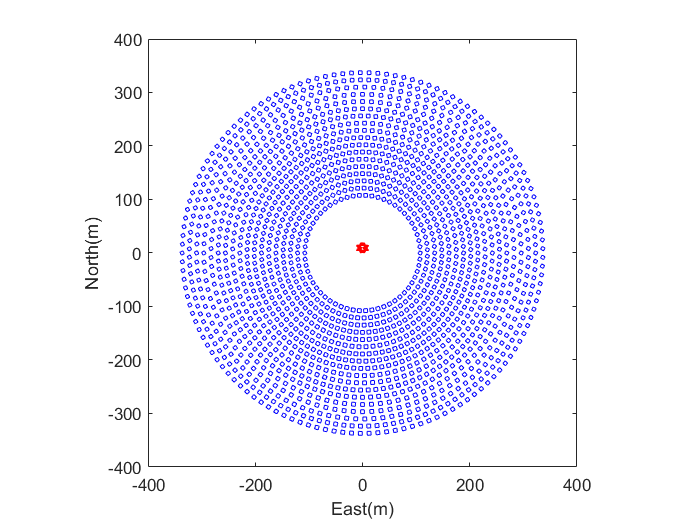

clc;clear
load P
load hidde_s
light_s = 36-hidde_s;
eltasb = light_s/36;
cmap = jet(100); % 创建一个有100种颜色的颜色映射
for i = 1:length(P)
P1 = P{i};
plot(P1(:,1), P1(:,2),'b');
hold on;
end
axis square 
hold on
x = -3.5:0.01:3.5;
y = sqrt(10^2-x.^2);
plot(x,y,'r','Marker','hexagram')
xlabel('East(m)')
ylabel('North(m)')
saveas(gcf,'初始日镜分布图.png','png')